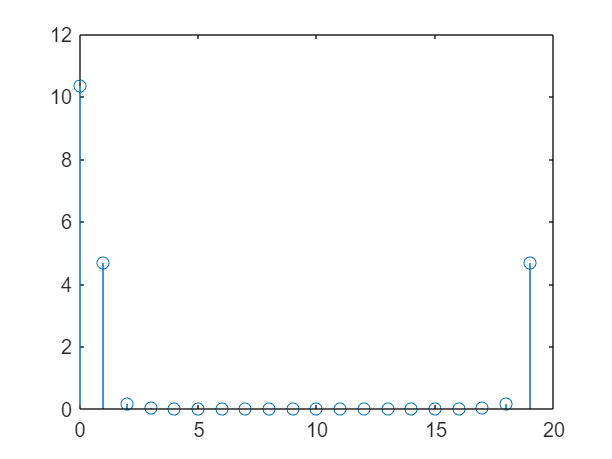

% 5.2.1
x=hamming(20);
X_20=DFTsum(x.');
n=0:19;
figure
stem(n,abs(X_20));

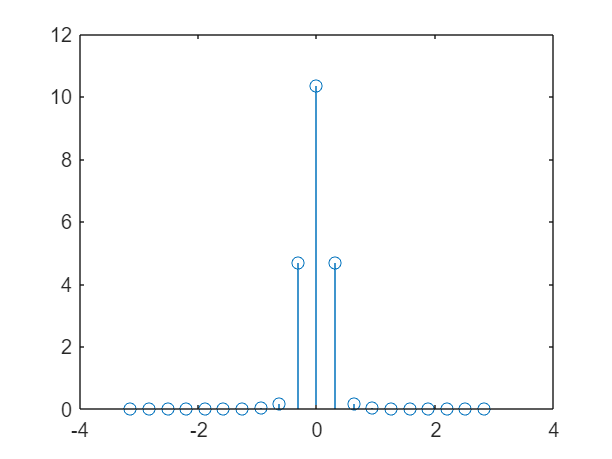

[X,w]=DTFTsamples(x.');
figure
stem(w,abs(X));

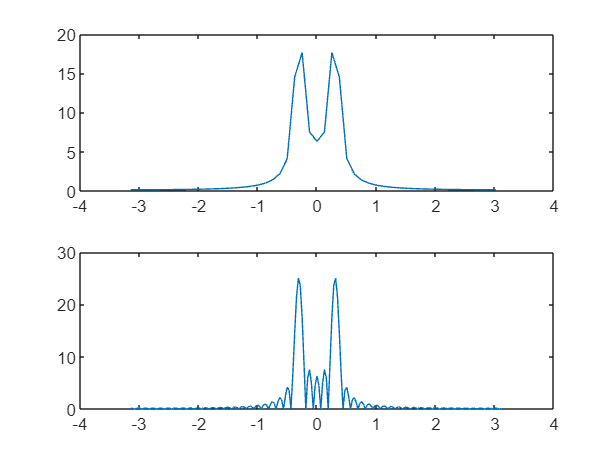

% 5.2.2
n1=0:50-1;
x1=sin(0.1*pi*n1);
[X1,w1]=DTFTsamples(x1);
n2=0:200-1;
x2=[x1,zeros(1,200-50)];
[X2,w2]=DTFTsamples(x2);
figure
subplot(211)
plot(w1,abs(X1));
subplot(212)
plot(w2,abs(X2));

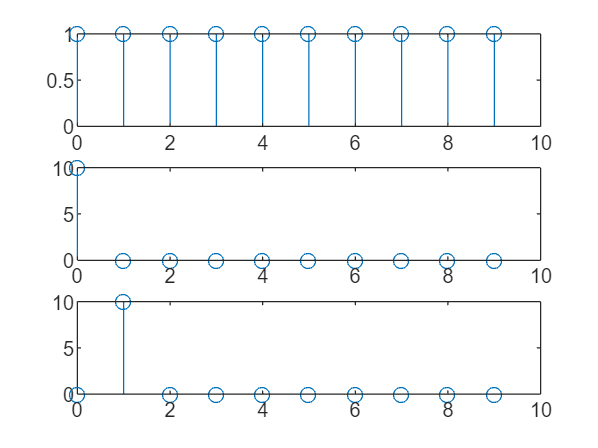

% 5.3.1
N=10;
n=0:N-1;
x1=(n==0);
x2=ones(N);
x3=exp(1i*2*pi*n/N);
X1=dcDFT(x1);
X2=dcDFT(x2);
X3=dcDFT(x3);
figure
subplot(311)
stem(n,abs(X1))
subplot(312)
stem(n,abs(X2))
subplot(313)
stem(n,abs(X3))

% N^2/2+N

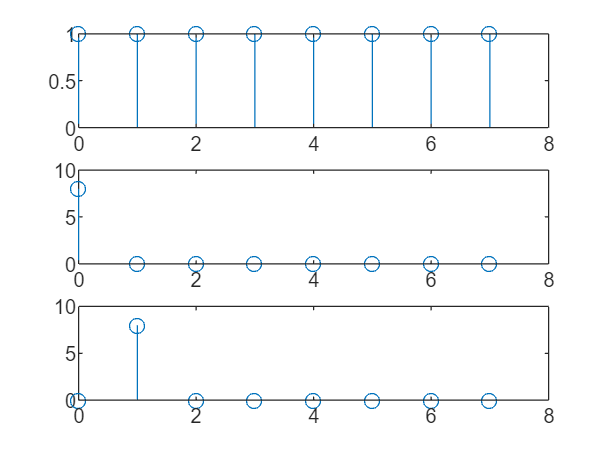

% 5.3.2
N=8;
n=0:N-1;
x1=(n==0);
x2=ones(N);
x3=exp(1i*2*pi*n/N);
X1=FFT8(x1);
X2=FFT8(x2);
X3=FFT8(x3);
figure
subplot(311)
stem(n,abs(X1))
subplot(312)
stem(n,abs(X2))
subplot(313)
stem(n,abs(X3))

ans = -6.3068 + 3.0372i

%(3-1)*8=16 
%(N-1)lgN=p*(2^p-1)  vs  N^2=2^(2p)

X1=fft_stage(x1);
X2=fft_stage(x2);
X3=fft_stage(x3);
figure
subplot(311)
stem(n,abs(X1))
subplot(312)
stem(n,abs(X2))
subplot(313)
stem(n,abs(X3))